# Bayesian parameter inference

# Exploratory Data analysis.

First thing we should do is look at the data!

cd ('/Users/razo/Documents/PhD/teaching/MBL_Physiology_2016/code/bayesian_inference')
df = readtable('flow_master.csv');

df(1:5,:)

ans =        date        username     operator    binding_energy       rbs       repressors    IPTG_uM    mean_YFP_A    mean_YFP_bgcorr_A    fold_change_A
    __________    __________    ________    ______________    _________    __________    _______    __________    _________________    _____________

    2.0161e+07    'mrazomej'    'O2'        -13.9             'auto'         0           0          3512.6             0                       0    
    2.0161e+07    'mrazomej'    'O2'        -13.9             'delta'        0           0           19164         15652                       1    
    2.0161e+07    'mrazomej'    'O2'        -13.9        

## Boolean indexing with tidy data frames

O2_rows = strcmp(df.operator,'O2');
df_O2 = df(O2_rows, :);
df_O2(1:5, :)

ans =        date        username     operator    binding_energy       rbs       repressors    IPTG_uM    mean_YFP_A    mean_YFP_bgcorr_A    fold_change_A
    __________    __________    ________    ______________    _________    __________    _______    __________    _________________    _____________

    2.0161e+07    'mrazomej'    'O2'        -13.9             'auto'         0           0          3512.6             0                       0    
    2.0161e+07    'mrazomej'    'O2'        -13.9             'delta'        0           0           19164         15652                       1    
    2.0161e+07    'mrazomej'    'O2'        -13.9        

## Guided Struggle : Extract the O2 RBS1027 data

O2_1027_rows = strcmp(df.operator, 'O2') & strcmp(df.rbs, 'RBS1027');
df_fit = df(O2_1027_rows, :);

## Time to look at the data

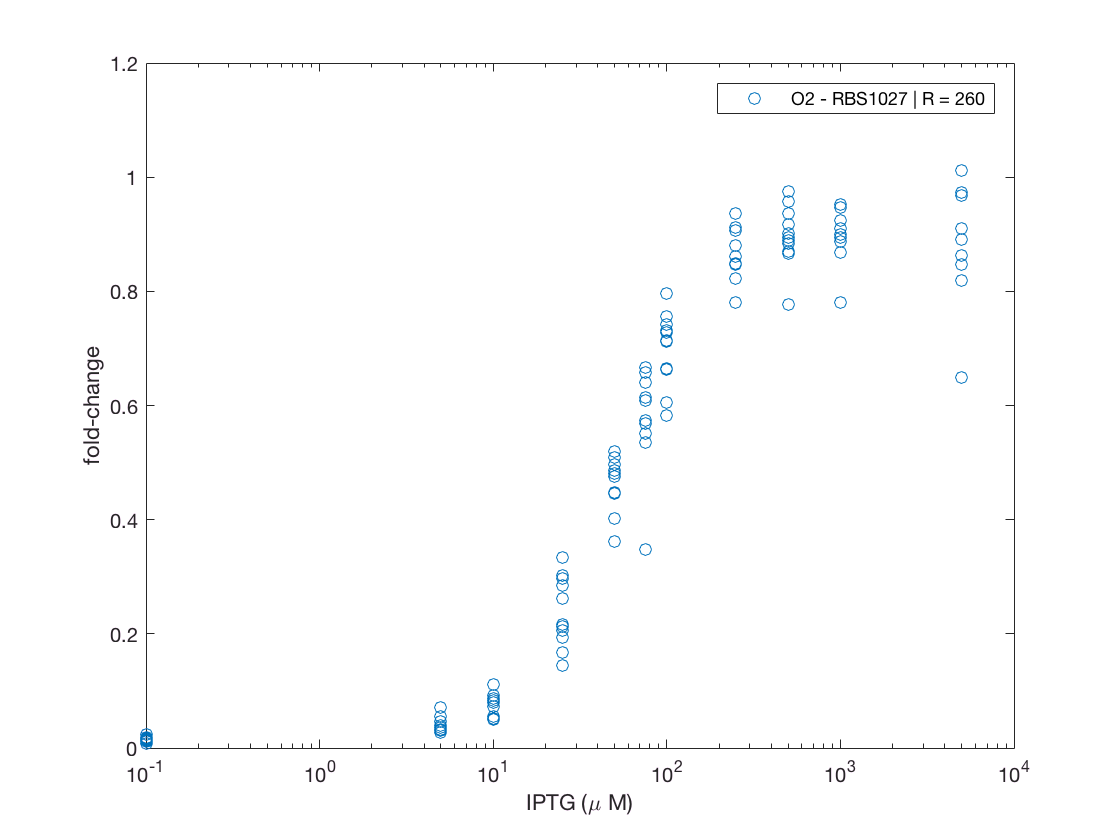

semilogx(df_fit.IPTG_uM, df_fit.fold_change_A, 'o')
xlabel('IPTG (\mu M)')
ylabel('fold-change')
legend('O2 - RBS1027 | R = 260')

## Plot mean and standard error

% Extract the unique IPTG concentrations
IPTG = unique(df_fit.IPTG_uM);

% Initialize arrays to save mean, std and number of samples for each IPTG concentration
mean_fc = [];
sd_fc = [];
num_fc = [];
% Loop through each IPTG concentrations. Extract the data, compute the mean, SD
% and count the number of data points
for c=1:length(IPTG)
    % First step: Extract the data
    df_tmp = table2array(df_fit(df_fit.IPTG_uM==IPTG(c), 'fold_change_A'));
    % Second step: compute mean fc and store it
    mean_fc(c) = mean(df_tmp);
    % Third step: compute standard deviation and store it
    sd_fc(c) = std(df_tmp);
    % Fourth and last step: count the number of data points and store them
    num_fc(c) = length(df_tmp);
end %for

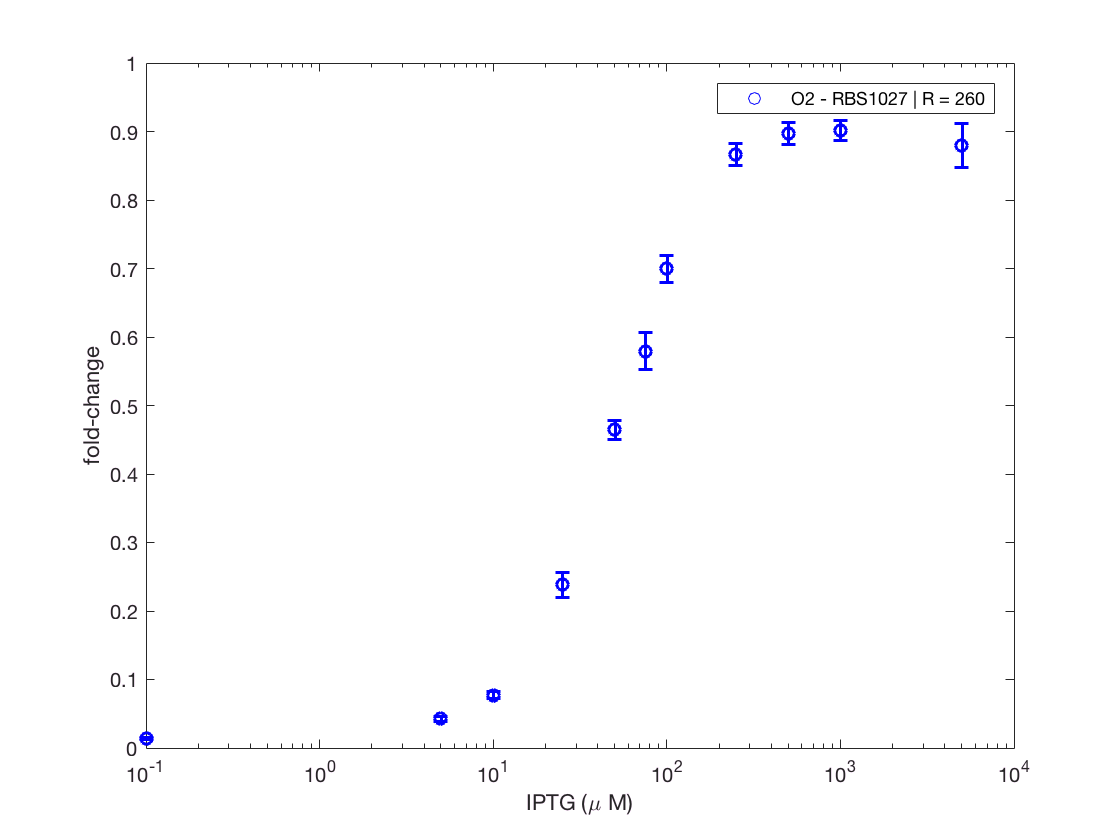

% Plot mean and error bars
clf
semilogx(IPTG, mean_fc, 'ob')
hold on
errorbar(IPTG, mean_fc, sd_fc ./ sqrt(num_fc), 'ob', 'Linewidth', 1.5)
xlabel('IPTG (\mu M)')
ylabel('fold-change')
legend('O2 - RBS1027 | R = 260')
hold off

## Defining functions for $p_{act}$ and fold-change

Let's test these functions by plotting the fold-change for some parameter values.

% Defining the parameters for the function
R = 130; % repressors / cell
epsilon_R = -13.9; % kBT
ea = 5; % kBT
ei = -1; % kBT
epsilon = 4.5; % kBT
%  Define range of IPTG in log-scale
IPTG_array = logspace(-1, 4, 100); % µM

%  Let's compute the fold-change using these parameters
fc_thry = fold_change(IPTG_array, ea, ei, R, epsilon_R, epsilon);

Let's now plot the fold-change

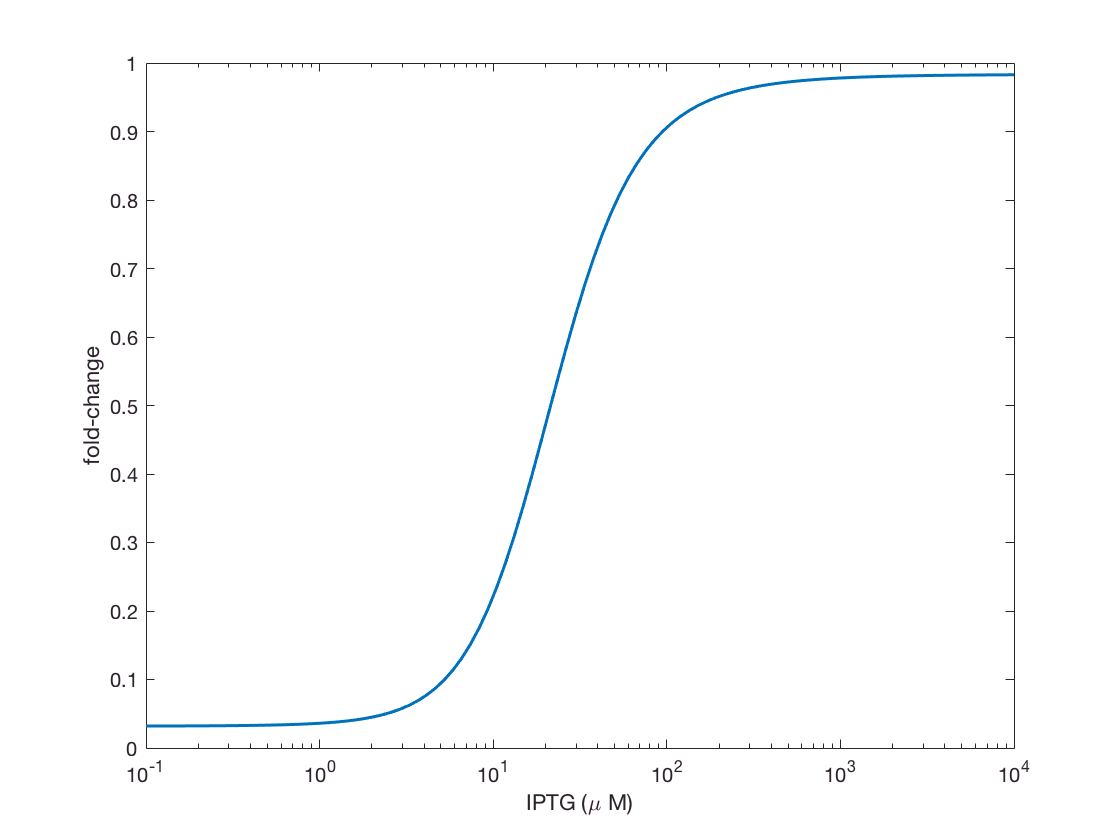

% Plot IPTG vs fold-change
semilogx(IPTG_array, fc_thry, 'Linewidth', 1.5)
xlabel('IPTG (\mu M)')
ylabel('fold-change')

## Define the log posterior $\log (\varepsilon \mid D)$